# Asymmetric Tuning Curves of UP and DOWN ON DSGCs and Implications for Population Coding

downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

## Population Tuning Curves

By taking the average response for all UP and DOWN cells in each of 8 directions, we can plot the mean population tuning curve for each cell type (normalized to the maximum firing rate of each individual cell). These curves are fit here using cosine models with a period of 360 degrees. The cosine fit appears to deviate further from the population average of DOWN cells than it does from that of UP cells. More specifically, the population average of DOWN cells is more broadly tuned than that of UP cells, with a large domain in which responses are saturated for stimuli between 180 and 360 degrees.

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

allOrientations = [0:45:315];
upVals = zeros(0, numel(allOrientations));
upValsNonNormalized = zeros(0, numel(allOrientations));
downVals = zeros(0, numel(allOrientations));
downValsNonNormalized = zeros(0, numel(allOrientations));
upPDs = [];
downPDs = [];
upDSIs = zeros(size(ups, 1), 1);
downDSIs = zeros(size(downs, 1), 1);
upDSIs_simple = zeros(size(upDSIs));
downDSIs_simple = zeros(size(downDSIs));

uperrs = [];
upRoundedPDs = [];
upClockwise90 = [];
upCounterClock90 = [];

downerrs = [];
downRoundedPDs = [];
downClockwise90 = [];
downCounterClock90 = [];

up270DegAllResponses = cell(size(ups, 1), 1);
up225DegAllResponses = cell(size(ups, 1), 1);
up315DegAllResponses = cell(size(ups, 1), 1);
up0DegAllResponses = cell(size(ups, 1), 1);
up360DegAllResponses = cell(size(ups, 1), 1);
down270DegAllResponses = cell(size(downs, 1), 1);
down225DegAllResponses = cell(size(downs, 1), 1);
down315DegAllResponses = cell(size(downs, 1), 1);
down0DegAllResponses = cell(size(downs, 1), 1);
down360DegAllResponses = cell(size(downs, 1), 1);

up_PD_SNR = [];
up_ND_SNR = [];
down_PD_SNR = [];
down_ND_SNR = [];
animals = {};
indexer = 0;
us = {};
%grab data for up cells
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    us(end + 1) = {struct_i.cellID};
    indexer = indexer +1;
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    stdSpikes = loc.Analysis_Results.std_spikesByOrientation;
    
    for j = 1:numel(orientations)
        o_j = orientations(j);
        upVals(indexer, allOrientations == o_j) = spikes(j);
    end
    upValsNonNormalized(indexer, :) = upVals(indexer, :);
    upVals(indexer, :) = upVals(indexer, :)/max(upVals(indexer, :)); %normalize
    upDSIs(indexer) = loc.Analysis_Results.DSI;
    
    [uperr, roundedPD_Index] = min(abs(orientations - mod(loc.Analysis_Results.PreferredDirection, 360)));
    roundedPD = orientations(roundedPD_Index);
    uperrs(indexer) = uperr * sign(roundedPD - mod(loc.Analysis_Results.PreferredDirection, 360));
    upPDs(indexer) = mod(loc.Analysis_Results.PreferredDirection, 360);
    upRoundedPDs(indexer) = roundedPD;
    upClockwise90(indexer) = spikes(orientations == mod(roundedPD + 90, 360))/spikes(roundedPD_Index);
    upCounterClock90(indexer) = spikes(orientations == mod(roundedPD - 90, 360))/spikes(roundedPD_Index);
    
    PDResponse = spikes(orientations == mod(roundedPD,360));
    up_PD_SNR(end + 1) = PDResponse/stdSpikes(orientations == mod(roundedPD, 360));
    NDResponse = spikes(orientations == mod(roundedPD+180,360));
    up_ND_SNR(end + 1) = NDResponse/stdSpikes(orientations == mod(roundedPD + 180, 360));
    upDSIs_simple(indexer) = (PDResponse-NDResponse)/(PDResponse+NDResponse);
    
    up270DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 270, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    up225DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 225, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    up315DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 315, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    up0DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 0, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    up180DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 180, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    animals(end + 1) = {struct_i.cellID(1:7)};
end

upDSIs = upDSIs(1:indexer);
upDSIs_simple = upDSIs_simple(1:indexer);
up270DegAllResponses = up270DegAllResponses(1:indexer);
up225DegAllResponses = up225DegAllResponses(1:indexer);
up315DegAllResponses = up315DegAllResponses(1:indexer);
up0DegAllResponses = up0DegAllResponses(1:indexer);
up360DegAllResponses = up360DegAllResponses(1:indexer);
upMean = mean(upVals);

indexer = 0;
ds = {};
%grab data for down cells
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    ds(end + 1) = {struct_i.cellID};
    indexer = indexer + 1;
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    stdSpikes = loc.Analysis_Results.std_spikesByOrientation;
    
    for j = 1:numel(orientations)
        o_j = orientations(j);
        downVals(indexer, allOrientations == o_j) = spikes(j);
    end
    downValsNonNormalized(indexer, :) = downVals(indexer, :);
    downVals(indexer, :) = downVals(indexer, :)/max(downVals(indexer, :));
    downDSIs(indexer) = loc.Analysis_Results.DSI;
    
    [downerr, roundedPD_Index] = min(abs(orientations - mod(loc.Analysis_Results.PreferredDirection, 360)));
    roundedPD = orientations(roundedPD_Index);
    downerrs(indexer) = downerr * sign(roundedPD - mod(loc.Analysis_Results.PreferredDirection, 360));
    downPDs(indexer) = mod(loc.Analysis_Results.PreferredDirection, 360);
    downRoundedPDs(indexer) = roundedPD;
    downClockwise90(indexer) = spikes(orientations == mod(roundedPD + 90, 360))/spikes(roundedPD_Index);
    downCounterClock90(indexer) = spikes(orientations == mod(roundedPD - 90, 360))/spikes(roundedPD_Index);
    
    PDResponse = spikes(orientations == mod(roundedPD,360));
    down_PD_SNR(end + 1) = PDResponse/stdSpikes(orientations == mod(roundedPD, 360));
    NDResponse = spikes(orientations == mod(roundedPD+180,360));
    down_ND_SNR(end + 1) = NDResponse/stdSpikes(orientations == mod(roundedPD + 180, 360));
    downDSIs_simple(indexer) = (PDResponse-NDResponse)/(PDResponse+NDResponse);
    
    down270DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 270, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    down225DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 225, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    down315DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 315, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    down0DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 0, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    down180DegAllResponses{indexer} = [loc.Analysis_Results.spikesByOrientation{orientations == 180, 2}]./spikes(roundedPD_Index); %best way to do this is to normalize to the maximum epoch, but it's a bit easier to just normalize to the mean preferred direction response. Consider changing later
    animals(end + 1) = {struct_i.cellID(1:7)};
end
downDSIs = downDSIs(1:indexer);
downDSIs_simple = downDSIs_simple(1:indexer);
down270DegAllResponses = down270DegAllResponses(1:indexer);
down225DegAllResponses = down225DegAllResponses(1:indexer);
down315DegAllResponses = down315DegAllResponses(1:indexer);
down0DegAllResponses = down0DegAllResponses(1:indexer);
down360DegAllResponses = down360DegAllResponses(1:indexer);
downMean = mean(downVals);

%gaussian fit population tuning curves
[fitDownParams, fitDownXs, fitDownVals] = sinewaveFit(allOrientations, downMean);
close all
[fitUpParams, fitUpXs, fitUpVals] = sinewaveFit(allOrientations, upMean);
close all

DataAvailability = struct();

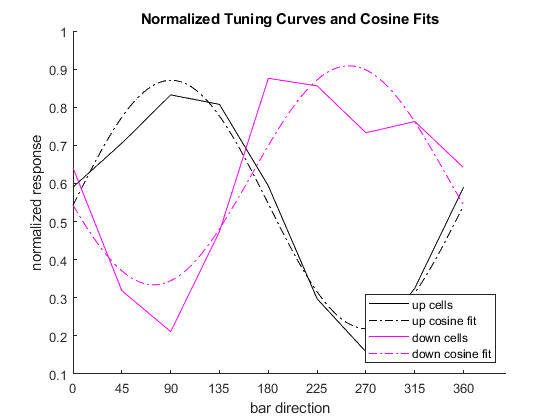

%Tuning curves
figure
plot([allOrientations 360], [upMean upMean(1)],'-k')
hold on
plot(fitUpXs, fitUpVals, '-.k')
plot([allOrientations 360], [downMean downMean(1)], '-m');
plot(fitDownXs, fitDownVals, '-.m')
title('Normalized Tuning Curves and Cosine Fits')
lgd = legend({'up cells', 'up cosine fit', 'down cells', 'down cosine fit'});
lgd.Location = 'southeast';
ylabel('normalized response')
xlabel('bar direction')
box off
xticks([0:45:360])

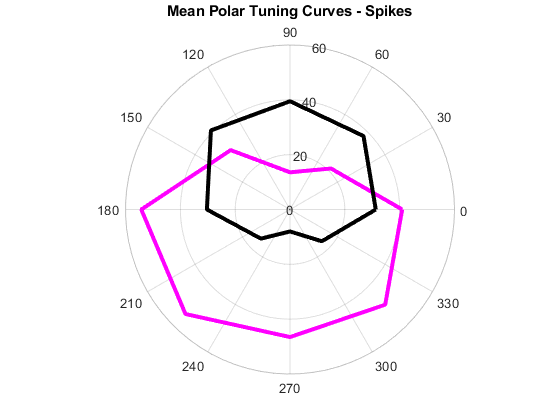

upMeanNonNormalized = mean(upValsNonNormalized);
downMeanNonNormalized = mean(downValsNonNormalized);

figure
polarplot(deg2rad([0:45:360]), [downMeanNonNormalized, downMeanNonNormalized(1)], '-m', 'LineWidth', 3)
hold on
polarplot(deg2rad([0:45:360]), [upMeanNonNormalized, upMeanNonNormalized(1)], 'k', 'LineWidth', 3)
title('Mean Polar Tuning Curves - Spikes')

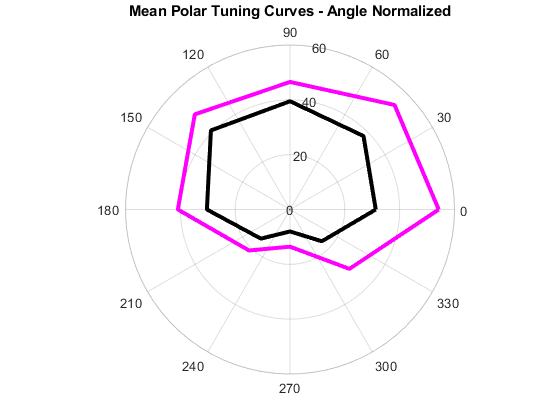

figure
polarplot(deg2rad([0:45:360]), [downMeanNonNormalized(5:8), downMeanNonNormalized(1:5)], '-m', 'LineWidth', 3)
hold on
polarplot(deg2rad([0:45:360]), [upMeanNonNormalized, upMeanNonNormalized(1)], 'k', 'LineWidth', 3)
title('Mean Polar Tuning Curves - Angle Normalized')

[upDSI, upVector] = calculateDSI([0:45:315], upMeanNonNormalized)

upDSI = 0.2961

upVector =    90.1117   64.9025


[downDSI, downVector] = calculateDSI([0:45:315], downMeanNonNormalized)

downDSI = 0.2356

downVector =  -108.7132   73.0521


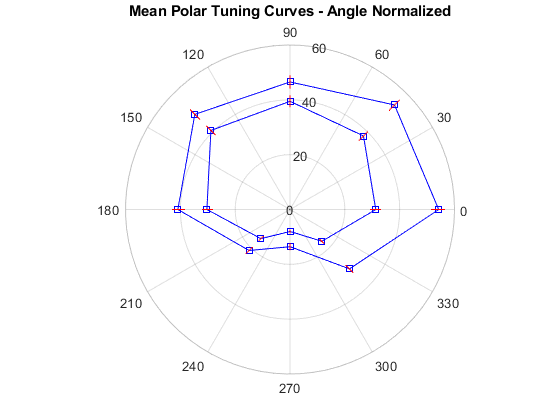

%convert to cartesian so you can get the error
dErr = std(downValsNonNormalized)/sqrt(size(downValsNonNormalized, 1));

uErr = std(upValsNonNormalized)/sqrt(size(upValsNonNormalized, 1));

figure
polarwitherrorbar(deg2rad([0:45:360]), downMeanNonNormalized([5:8, 1:5]), dErr([5:8, 1:5]))
hold on
polarwitherrorbar(deg2rad([0:45:360]), upMeanNonNormalized([1:8, 1]), uErr([1:8, 1]))
title('Mean Polar Tuning Curves - Angle Normalized')

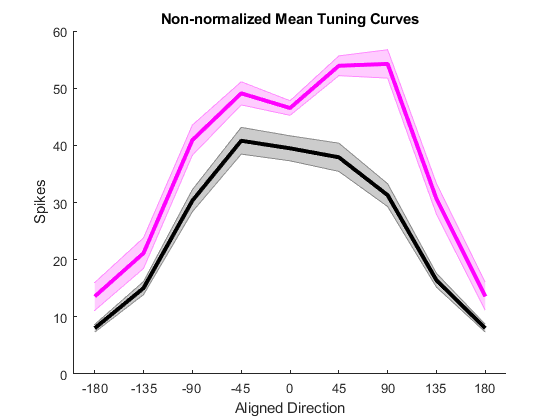

curveOrientations = [-180:45:180];
figure
title('Non-normalized Mean Tuning Curves')
hold on
shadedErrorBar(curveOrientations, upMeanNonNormalized([7:-1:1, 8, 7]), uErr([7:-1:1, 8, 7]), 'LineProps', {'k', 'LineWidth', 3})
shadedErrorBar(curveOrientations, downMeanNonNormalized([3:-1:1, 8:-1:3]), dErr([3:-1:1, 8:-1:3]), 'LineProps', {'m', 'LineWidth', 3})
xlabel('Aligned Direction')
ylabel('Spikes')
xticks([-180:45:180])

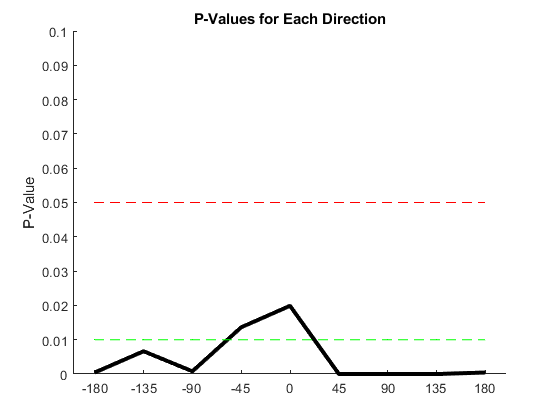

upValsNonNormalized;
downValsNonNormalized;
ps = zeros(1, numel(orientations));
dRotated = [downValsNonNormalized(:, 5:8), downValsNonNormalized(:, 1:4)];

for i = 1:numel(orientations)
    dGroup = dRotated(:, i);
    uGroup = upValsNonNormalized(:, i);
    ps(i) = ranksum(dGroup, uGroup);
end
figure
title('P-Values for Each Direction')
hold on
plot(curveOrientations, ps([7:-1:1, 8, 7]), 'k', 'linewidth', 3)
plot(curveOrientations, zeros(size(curveOrientations))+0.01, '--g')
plot(curveOrientations, zeros(size(curveOrientations))+0.05, '--r')
ylim([0, 0.1])
ylabel('P-Value')
xticks([-180:45:180])

ps = ps([7:-1:1, 8, 7])

ps =     0.0004    0.0066    0.0008    0.0136    0.0199    0.0000    0.0000    0.0000    0.0004


DataAvailability.CellAttachedTuningCurves.MeanTuningCurve.Superior.MeanTuningCurve = downMeanNonNormalized([3:-1:1, 8:-1:3]);
DataAvailability.CellAttachedTuningCurves.MeanTuningCurve.Superior.StandardError = dErr([3:-1:1, 8:-1:3]);
DataAvailability.CellAttachedTuningCurves.MeanTuningCurve.Inferior.Mean = upMeanNonNormalized([7:-1:1, 8, 7]);
DataAvailability.CellAttachedTuningCurves.MeanTuningCurve.Inferior.StandardError = uErr([7:-1:1, 8, 7]);

## Individual Tuning Curves

What accounts for the broader population tuning curve of DOWN cells? I can think of two possible explanations: 1) Individual DOWN cells each have cosine-like tuning functions, but together are tuned to a wide swath of preferred directions. In this scenario, the population tuning curve is broadened due to diversity of preferred directions across cells, but the tuning curves of individual cells are nonetheless cosine-shaped; 2) Individual down cells themselves have wider tuning curves than UP cells.

### Scenario 1

To test the first possibility, I will compare the distribution of preferred directions for UP and DOWN cells. The histogram below shows the number of degrees that the preferred direction of each cell deviates from the vertical axis. A negative value indicates that the cell's preferred direction deviates in a clockwise direction. A positive number means it deviates in the counter clockwise direction. 

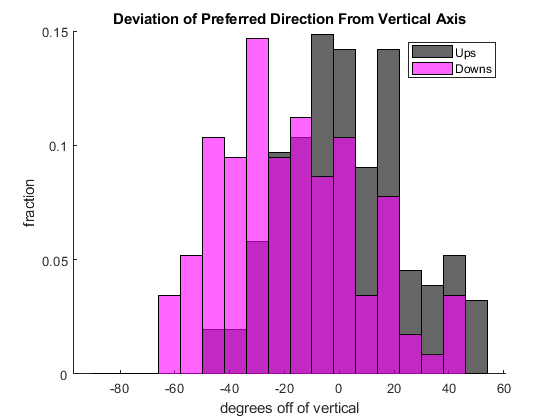

edgs = -90:8:60;

figure
title('Deviation of Preferred Direction From Vertical Axis')
hold on
histogram(upPDs - 90, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization','probability')
histogram(downPDs - 270, 'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability')
legend('Ups', 'Downs')
xlabel('degrees off of vertical')
ylabel('fraction')

disp(['p = ', num2str(ranksum(upPDs - 90, downPDs-270))])

p = 1.4198e-10


% A better way to do this is actually to run a statistical test to compare
% variances. The nonparametric test for this is the conover squared rank
% test, but it is uncommon. The parametric test is the F-test, which is
% much more common and has a built in matlab function. However, in order to
% this, we must first gain some confidence that the distributions of
% preferred directions are normally distributed.

% To test for normality, we'll run a Kolmogorov-Smirnov test:
normalizedUpPDs = (upPDs - mean(upPDs))/std(upPDs);
normalizedDownPDs = (downPDs - mean(downPDs))/std(downPDs);
[~, p] = kstest(normalizedUpPDs)

p = 0.7662

[~, p] = kstest(normalizedDownPDs)

p = 0.4115


% We fail to reject the null hypothesis that the distributions are normal.
% This doesn't mean that they *are* normal, but at least we don't have any
% evidence to the contrary. Now that we've established this, let's run a
% comparison of variance test on them
[~, p] = vartest2(upPDs, downPDs)

p = 0.2188


%Again, we see a non zero p - value, indicating that there is no
%significant difference between the variances of preferred directions in UP
%and DOWN cells.

The p-value indicates no significant difference between the groups. Therefore, we cannot claim that down cells are tuned to a broader array of directions than up cells. The remaining possibility is that down cells are more broadly tuned than up cells on an individual, cell by cell basis.

Update 6/30/2021 - the P-value for this has now become significant. Down cells seem to point slightly more off access than UP cells. What is possibly important is seeing if there's a difference in something like the standard deviation since perhaps the preferred direction for down cells is actually better described as slightly less than 270 degrees.

### Scenario 2

Next, we'll test whether a difference in tuning curve shape on a cell-by-cell basis can account for the differences between the population tuning curves of UP and DOWN cells. The plots in this section look at the firing rate of both UP and DOWN cells to stimuli that are 90 degrees away from their preferred direction (i.e. to horizontal motion). More specifically, I am plotting

 
$$\frac{\textrm{number}\;\textrm{of}\;\textrm{spikes}\;\textrm{for}\;\mathrm{a}\;\textrm{stimulus}\;\textrm{that}\;\textrm{is}\;90\;\textrm{degrees}\;\textrm{off}\;\textrm{of}\;\textrm{the}\;\textrm{preferred}\;\textrm{direction}}{\textrm{number}\;\textrm{of}\;\textrm{spikes}\;\textrm{for}\;\mathrm{a}\;\textrm{stimulus}\;\textrm{in}\;\textrm{the}\;\textrm{preferred}\;\textrm{direction}}$$


In so doing, the response in the (roughly) horizontal direction is normalized by the number of spikes in the preferred direction to account for basline variability in each cell's firing rate. Therefore, the resulting number describes only the *shape *of the tuning curve for each cell, not its magnitude (i.e. scale). The broader the tuning curve for an individual cell, the larger this number will be.

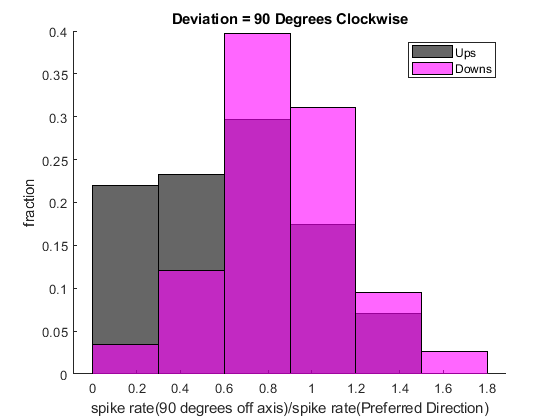

figure
title('Deviation = 90 Degrees Clockwise')
hold on
histogram(upClockwise90, 'BinEdges', 0:0.3:2, 'FaceColor', 'black', 'Normalization','probability')
histogram(downClockwise90, 'BinEdges', 0:0.3:2, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability')
legend('Ups', 'Downs')
xlabel('spike rate(90 degrees off axis)/spike rate(Preferred Direction)')
ylabel('fraction')

disp(['p = ', num2str(ranksum(upClockwise90, downClockwise90))])

p = 9.1438e-07


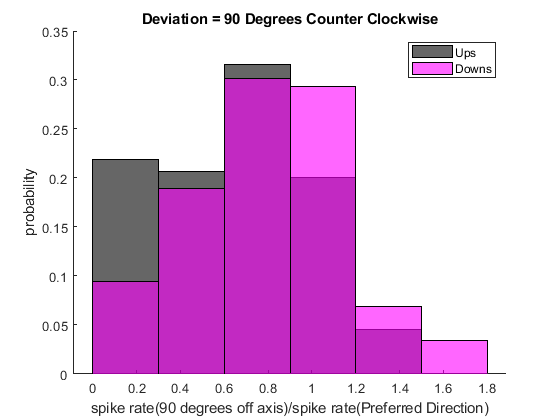

% figure
% scatter(rand(numel(upClockwise90), 1)/2, upClockwise90, 'k')
% hold on
% scatter(rand(numel(downClockwise90), 1)/2 + 1, downClockwise90, 'm')
% xticklabels({''})

figure
title('Deviation = 90 Degrees Counter Clockwise')
hold on
histogram(upCounterClock90, 'BinEdges', 0:0.3:2, 'FaceColor', 'black', 'Normalization','probability')
histogram(downCounterClock90, 'BinEdges', 0:0.3:2, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability')
legend('Ups', 'Downs')
xlabel('spike rate(90 degrees off axis)/spike rate(Preferred Direction)')
ylabel('probability')

disp(['p = ', num2str(ranksum(upCounterClock90, downCounterClock90))])

p = 0.00085314


This analysis shows that DOWN cells tend to have broader tuning curves than UP cells. This feature of the individual tuning curves of DOWN cells does not appear to average out when looking at the population tuning curve. Instead, the population curve for DOWN cells inherits its broadness from the shape of the tuning curve of individual DOWN cells.

### Von Mises Fits

The Von Mises function can serve as an alternative fit to the cosine function. It is an approximation to the circular gaussian. Here, I track the Kappa parameter of Von Mises fits for each cell in the data. Kappa represents the width of the tuning curve, with higher values corresponding to narrower widths. Kappa can be arbitrarily large but is constrained to be greater than 0.

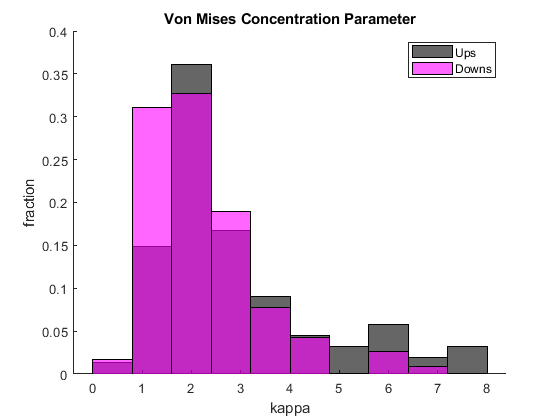

vMFUp = zeros(size(upVals, 1), 1);
vMEUp = zeros(size(upVals, 1), 1);
vMFDown = zeros(size(downVals, 1), 1);
vMEDown = zeros(size(downVals, 1), 1);
angles = 0:45:315;

for i = 1:numel(vMFUp)
    [p, e] = vonMisesFit(angles, (upVals(i, :)), deg2rad(90));
    vMFUp(i) = p(2); %add kappa parameter;
    vMEUp(i) = e; %keep track of error
end
for i = 1:numel(vMFDown)
    [p, e] = vonMisesFit(angles, (downVals(i, :)), deg2rad(270));
    vMFDown(i) = p(2); %add kappa parameter;
    vMEDown(i) = e;
end
figure
title('Von Mises Concentration Parameter')
hold on
histogram(vMFUp, 'BinEdges', 0:0.8:8, 'FaceColor', 'black', 'Normalization','probability')
histogram(vMFDown, 'BinEdges', 0:0.8:8, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability')
legend('Ups', 'Downs')
xlabel('kappa')
ylabel('fraction')

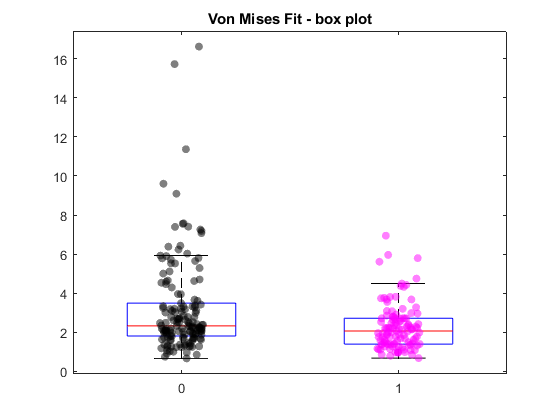

allPoints = [vMFUp; vMFDown];
groups = zeros(size(allPoints));
groups(numel(upDSIs):end, 1) = 1;

figure
title ('Von Mises Fit - box plot')
hold on
boxplot(allPoints, groups, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(size(vMFUp)).*(1+(rand(size(vMFUp))-0.5)/5),vMFUp,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(vMFDown)).*(1+(rand(size(vMFDown))-0.5)/5) + 1,vMFDown,'m','filled', 'MarkerFaceAlpha', 0.5)

disp(['p = ', num2str(ranksum(vMFUp, vMFDown))])

p = 0.00078165


median(vMFUp)

ans = 2.3295

median(vMFDown)

ans = 2.0522

DataAvailability.CellAttachedTuningCurves.VonMisesKappa.Superior = vMFDown;
DataAvailability.CellAttachedTuningCurves.VonMisesKappa.Inferior = vMFUp;
%Could also try getting a value for tuning curve width using the raised
%sinusoid function from Yao et al., 2018. As of 9/16/2021 I haven't yet
%been able to get this function to fit the tuning curves well.

% raisedSinUp = zeros(size(upVals, 1), 1);
% raisedSinEUp = zeros(size(upVals, 1), 1);
% raisedSinDown = zeros(size(downVals, 1), 1);
% raisedSinEDown = zeros(size(downVals, 1), 1);
% angles = 0:45:315;
%
% for i = 1:numel(raisedSinUp)
%     [p, e] = raisedSinusoidFit(angles, (upVals(i, :)), upVals(i, 7));
%     raisedSinUp(i) = 2*acos(2^(1-p(1)^-1)-1); %add alpha parameter;
%     raisedSinEUp(i) = e; %keep track of error
% end
% for i = 1:numel(raisedSinDown)
%     [p, e] = raisedSinusoidFit(angles, (downVals(i, :)), downVals(i, 3));
%     raisedSinDown(i) = 2*acos(2^(1-p(1)^-1)-1); %add width parameter;
%     raisedSinEDown(i) = e;
% end

### DSI is affected by tuning curve width

The direction selectivity index (DSI) can be calculated as the vector sum of a cell's response in each of eight directions, divided by the the total number of spikes that the cell fires in all eight directions together. Below, we see that the DSI of UP cells tends to be higher than that of DOWN cells on average.

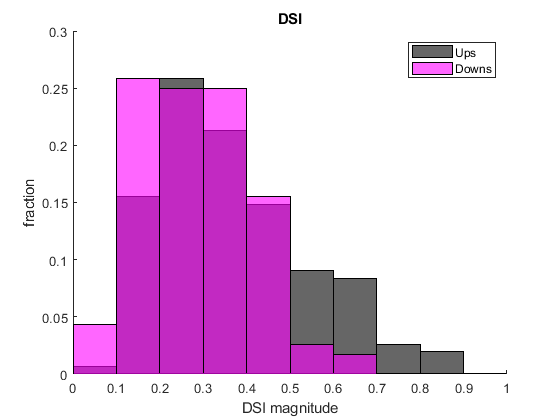

figure
title('DSI')
hold on
histogram(upDSIs, 'BinEdges', 0:0.1:1, 'FaceColor', 'black', 'Normalization', 'probability')
histogram(downDSIs,'BinEdges', 0:0.1:1, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability')
xlabel('DSI magnitude')
ylabel('fraction')
legend('Ups', 'Downs')
xlim([0 1])

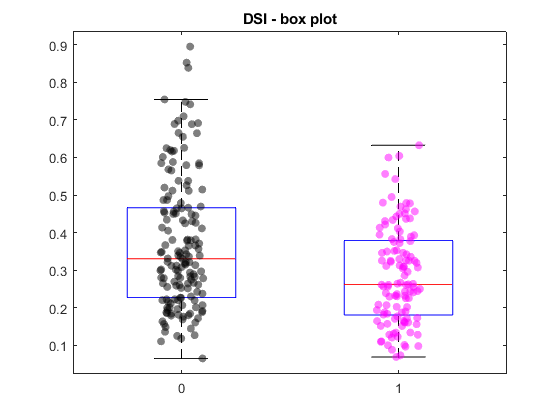

allPoints = [upDSIs; downDSIs];
groups = zeros(size(allPoints));
groups(numel(upDSIs):end, 1) = 1;

figure
title ('DSI - box plot')
hold on
boxplot(allPoints, groups, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(size(upDSIs)).*(1+(rand(size(upDSIs))-0.5)/5),upDSIs,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downDSIs)).*(1+(rand(size(downDSIs))-0.5)/5) + 1,downDSIs,'m','filled', 'MarkerFaceAlpha', 0.5)

disp(['p = ', num2str(ranksum(upDSIs, downDSIs))])

p = 0.0001139


disp(['Up Median DSI: ' num2str(median(upDSIs)) '; Down Median DSI: ' num2str(median(downDSIs))])

Up Median DSI: 0.33128; Down Median DSI: 0.2617


DataAvailability.CellAttachedTuningCurves.DSI.Superior = downDSIs;
DataAvailability.CellAttachedTuningCurves.DSI.Inferior = upDSIs;

This finding agrees with the previous: the broader tuning curve of DOWN cells lowers their direction selectivity. 

Interestingly, another popular definition of DSI is $\textrm{DSI}=\frac{\textrm{PD}\;-\;\textrm{ND}}{\textrm{PD}+\textrm{ND}}$  where PD is the response in the preferred direction and ND is the response in the null direction. Unlike the vector sum definition, this definition of DSI does not take into account the width of the tuning curve (e.g. it does not take into account the response of stimuli moving 90 degrees away from the preferred direction). Accordingly, we find no significant difference in the DSI of UP and DOWN cells when calculated using this second definition:

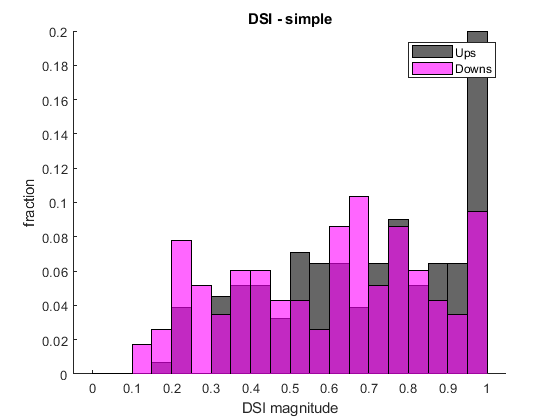

figure
title('DSI - simple')
hold on
histogram(upDSIs_simple, 'BinEdges', 0:0.05:1, 'FaceColor', 'black', 'Normalization','probability')
histogram(downDSIs_simple,'BinEdges', 0:0.05:1, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability')
xlabel('DSI magnitude')
ylabel('fraction')
legend('Ups', 'Downs')

disp(['p = ', num2str(ranksum(upDSIs_simple, downDSIs_simple))])

p = 0.0016694


## Noise in individual Cells

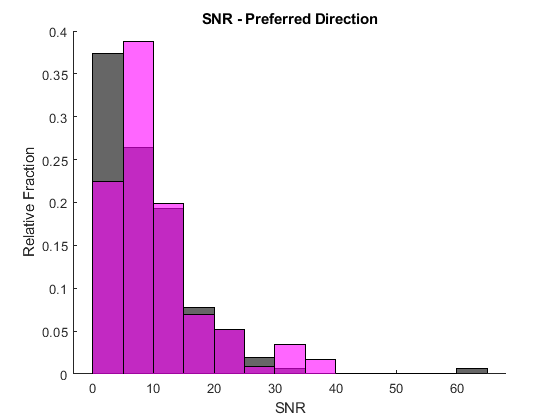

up_PD_SNR(isnan(up_PD_SNR)) = inf;
down_PD_SNR(isnan(down_PD_SNR)) = inf;
up_ND_SNR(isnan(up_ND_SNR)) = inf;
down_ND_SNR(isnan(down_ND_SNR)) = inf;
% Signal to noise ratio of preferred direction for individual cells
figure
title('SNR - Preferred Direction')
hold on
h1 = histogram(up_PD_SNR, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(down_PD_SNR, 'FaceColor', 'm', 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('SNR')
ylabel('Relative Fraction')

up_median = median(up_PD_SNR)

up_median = 6.9079

down_median = median(down_PD_SNR)

down_median = 7.8098

p = ranksum(up_PD_SNR, down_PD_SNR)

p = 0.0721

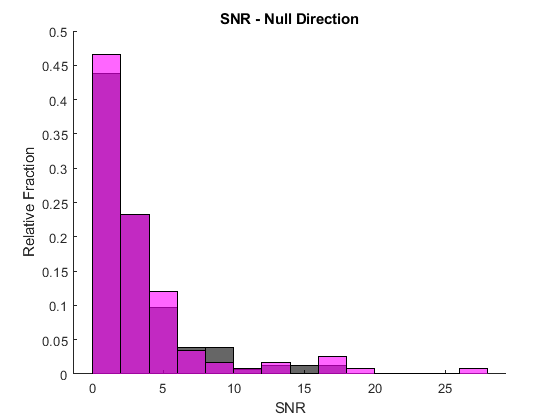


figure
title('SNR - Null Direction')
hold on
h1 = histogram(up_ND_SNR, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(down_ND_SNR, 'FaceColor', 'm', 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('SNR')
ylabel('Relative Fraction')

up_median = median(up_ND_SNR)

up_median = 2.3986

down_median = median(down_ND_SNR)

down_median = 2.2830

p = ranksum(up_ND_SNR, down_ND_SNR)

p = 0.8410

## Consequences for Population Coding

How do asymmetric tuning curves affect the ability of UP and DOWN cells to jointly encode moving stimuli? To address this question, I first plot the stimulus space that results from a case in which UP and DOWN cells both have smooth cosine-shaped tuning curves (specifically, this is the stimulus space calculated from the cosine functions fit in the first section).

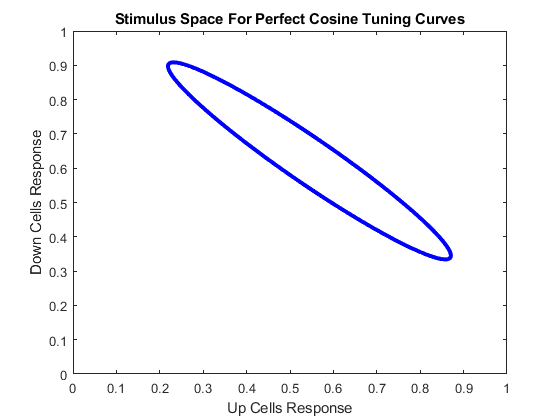

%response space
figure
plot(fitUpVals, fitDownVals, '.-b', 'LineWidth',3)
hold on
xlabel('Up Cells Response')
ylabel('Down Cells Response')
title('Stimulus Space For Perfect Cosine Tuning Curves');
xlim([0 1])
ylim([0 1])

The above curve plots the normalized response of UP and DOWN cells against each other for stimuli moving in any direction. As you can see, the joint responses stick to a well defined region of the stimulus space and reach the top left and bottom right of the curve when stimuli move straight down and straight up, respectively. (Note: the stimulus space curve in the plot above appears to be a single line because the two sides of the curve lie directly on top of each other).

In contrast, the next plot shows the empirically measured stimulus space based on the population tuning curves of recorded UP and DOWN cells

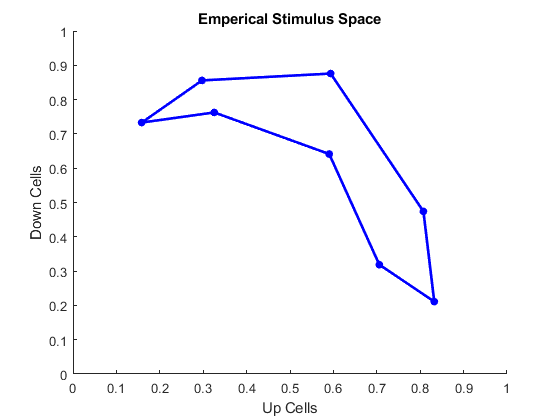

figure
title('Emperical Stimulus Space')
hold on
plot([upMean upMean(1)], [downMean, downMean(1)], '.-b', 'LineWidth', 2, 'MarkerSize', 20)
xlabel('Up Cells')
ylabel('Down Cells')
xlim([0 1])
ylim([0 1])

Unlike the stimulus space curve derived from perfect cosine fits, the empirical curve has two distinct domains: 1) In the bottom right, the first domain mirrors the response space from the cosine curve with a strong negative slope of approximately -1; 2) In the top left, however, there is a second, flat domain in which the slope of the curve is near 0. This is the response for all stimuli that move between 180 and 360 degrees. Further, it occurs because of the broadness of the DOWN cell tuning curve. More specifically, the DOWN cell response saturates between 180 and 360 degrees, meaning that this range of stimuli is only discriminated based on the diminishing response of UP cells as stimuli approach 270 degrees.

The empirical stimulus space curve is limited to 8 ordered pairs based on the number of stimuli that are used during experiments. To further understand the shape of the full response, I modeled the stimulus space for two exemplary cells: one with a perfect cosine tuning curve and one with a broad tuning curve which mirrors that of the DOWN cell population average. First, I show the tuning curves for these two model cells.

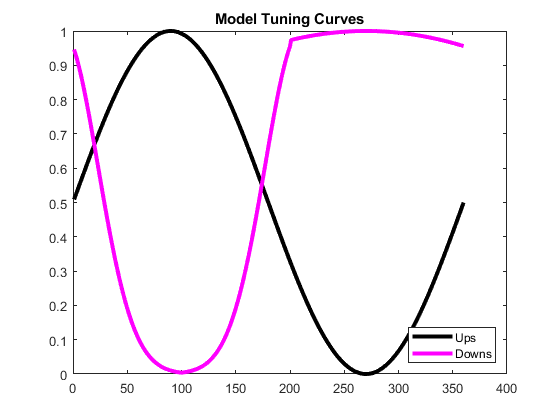

modelUp = @(x) 0.5*sin(x * 2*pi/360) + 0.5; %cosine fit with period 360 deg
modelDown = @(b, c, x) 1*exp(-((x - b).^2)./(2*c.^2)); %gaussian fit

xs = 1:360;
modelUpY = modelUp(xs);
modelDownY = [modelDown(-10,33, 1:100),...
    modelDown(210, 33, 101:200),  modelDown(270, 300, 201:360)]; %down cells are modeled by sum of 3 gaussians (it just approximates the overall shape

figure
plot(xs, modelUpY, '-k', 'LineWidth', 3)
hold on
plot(xs, modelDownY, '-m', 'LineWidth', 3)
title('Model Tuning Curves')
lgd = legend('Ups', 'Downs');
lgd.Location = 'southeast';

Next, I plot the stimulus space curve for these two model cells.

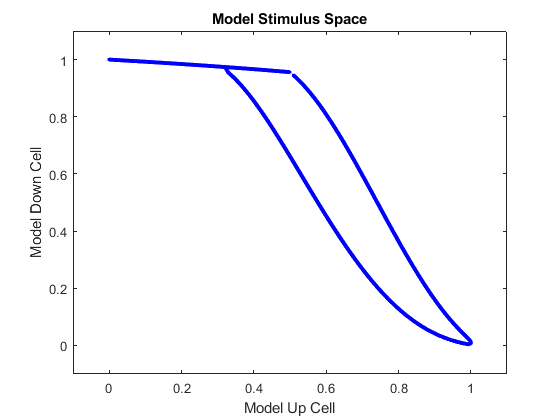

figure
plot(modelUpY, modelDownY, '.-b', 'LineWidth', 3)
hold on
title('Model Stimulus Space')
xlabel('Model Up Cell')
ylabel('Model Down Cell')
xlim([-0.1, 1.1])
ylim([-0.1, 1.1])

The shape of this curve clearly resembles that of the empirical stimulus space and contains the same two distinct domains in the top left and bottom right.

### Noise Implications

One clear consequence of a stimulus space curve of this shape is the potential impact of noise. One might expect noise to be correlated between UP and DOWN cells. Previous work suggests that if this noise is oriented orthogonal to the stimulus space curve, then its effect on coding is minimal. However, if the noise correlation has the same slope as the stimulus space curve, then it can be determental to the population code. Because the empirical and model stimulus space curves shown here each have two distinct domains with various slopes, I would predict that noise would have different effects in each of these domains. Specifically, it would appear that noise might corrupt the encoding of downward moving stimuli fairly signficantly because the slope of the response space curve is flat for stimuli between 180 and 360 degrees (therefore, the encoding of these stimuli relies almost entirely on the response of UP cells and any noise that occurs in these cells alone will corrupt the code). On the other hand, encoding of upward moving stimuli may be a bit more resilient because correlations between UP and DOWN cells in this regime can minimize the ability of noise in either cell to corrupt the code. I will explore two approaches for assessing the impact of noise on encoding downward stimuli.

#### SNR

Because coding relies entirely on the firing rate of UP cells in the upper left domain of the stimulus space curve, we can measure the influence of noise here without making simultaneous recordings from UP and DOWN cells. More specifcally, the noise in this regime is equal to (or very closely related to) the noise from UP cells. 

The following plot shows the distribution of the signal to noise ratio (SNR) for UP cells in response to stimuli moving 270 degrees.

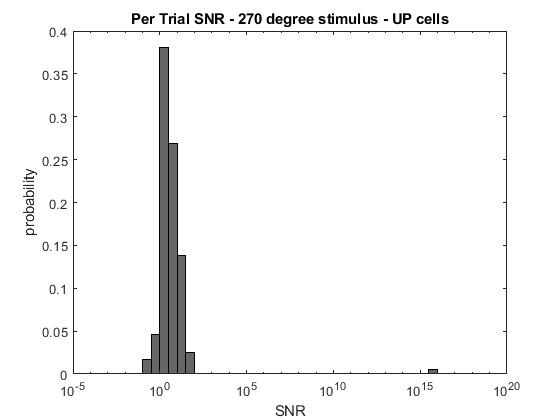

allNoise = [];
allResponses270 = [];
allResponses225 = [];
allResponses315 = [];
allResponses0 = [];
allResponses180 = [];
allSNR = [];
for i = 1:numel(up270DegAllResponses)
    allResponses270_i = up270DegAllResponses{i};
    if numel(allResponses270_i) < 3
        continue %skip if not enough trials at 270 for this cell
    end
    meanResponse_i = mean(allResponses270_i);
    noise_i = allResponses270_i - meanResponse_i; %noise is defined as the normalized response on a given epoch minus the normalized mean response for that cell. Normalization is done based on the average preferred direction response
    SNR_i = abs(meanResponse_i./noise_i);
    allNoise = [allNoise, noise_i];
    allResponses270 = [allResponses270, allResponses270_i];
    allResponses225 = [allResponses225, up225DegAllResponses{i}];
    allResponses315 = [allResponses315, up315DegAllResponses{i}];
    allResponses0 = [allResponses0, up0DegAllResponses{i}];
    allResponses180 = [allResponses180, up180DegAllResponses{i}];
    allSNR = [allSNR, SNR_i];
end


figure
[~,edges] = histcounts(log10(allSNR));
histogram(allSNR,'BinEdges', 10.^edges, 'FaceColor', 'k', 'Normalization', 'probability')
hold on
set(gca, 'xscale','log')
title('Per Trial SNR - 270 degree stimulus - UP cells')
xlabel('SNR')
ylabel('probability')

usableSNR = allSNR;
usableSNR(isnan(allSNR) | allSNR == Inf) = [];
disp(['The median of the SNR distribution is ' num2str(median(usableSNR))])

The median of the SNR distribution is 3.0971


An SNR value is calculated for every epoch of every UP cell. For a given epoch, the noise is defined as the cell's normalized response during that epoch, minus the normalized mean response of the cell to downward moving stimuli. The SNR of a given epoch is calculated as the normalized mean response of the cell divided by the absolute value of the noise on that epoch. I'm not sure this is the correct way to define SNR since it uses the mean response of the cell to calculate both the signal and the noise, but it was my best guess. The median of the SNR distribution is fairly high, indicating that, on average, only only about 25% of the total response is comprised of noise. Still, in looking at the empirical stimulus space curve in the previous section, a deviation of 25% rightwards from the mean response of UP cells to 270 degrees pushes the response about half of the distance towards the mean response for a stimulus that is 45 degrees off of the vertical axis (e.g. a 225 degree stimulus).

#### ROC

Another way of assessing the ability of the system to discriminate downward motion is using a receiver operating characteristic (ROC). The logic here is the same as above: because the stimulus space curve is flat for stimuli between 180 and 360 degrees, only activity in UP cells matters in discriminating among these stimuli. Below I plot a histogram of the normalized responses of UP cells to every epoch consisting of downward motion (270 degrees). On the same axes, I plot the responses of these same cells to motion that is 45 degrees away from straight down (i.e. 225 degrees or 315 degrees). Calculating the area under the curve (AUC) of the ROC tells us how seperable these two distributions are. If the AUC is 0.5, the two distributions overlap completely and, given a response, it is impossible to tell what the stimulus was. If the AUC is 1.0, the two distributions do not overlap at all and, given a response one can decode the stimulus that elicited it with 100% accuracy.

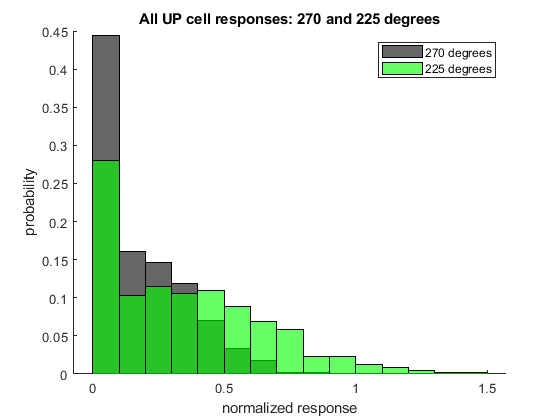


labels =  [zeros(1, numel(allResponses270)), ones(1, numel(allResponses225))];
scores = [allResponses270, allResponses225];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC225 = max([AUC, 1-AUC]);

edgs = 0:0.1:1.5;

figure
title('All UP cell responses: 270 and 225 degrees')
hold on
histogram(allResponses270,'BinEdges', edgs, 'FaceColor', 'black', 'Normalization','probability')
histogram(allResponses225, 'BinEdges', edgs, 'FaceColor', 'green', 'FaceAlpha', 0.6, 'Normalization','probability')
xlabel('normalized response')
ylabel('probability')
legend('270 degrees', '225 degrees')

disp(['The ROC AUC for these distributions is ' num2str(AUC225)])

The ROC AUC for these distributions is 0.66422


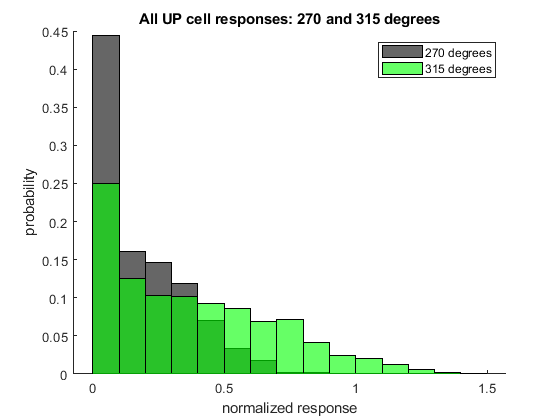

labels =  [zeros(1, numel(allResponses270)), ones(1, numel(allResponses315))];
scores = [allResponses270, allResponses315];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC315 = max([AUC, 1-AUC]);

figure
title('All UP cell responses: 270 and 315 degrees')
hold on
histogram(allResponses270,'BinEdges', edgs, 'FaceColor', 'black', 'Normalization','probability')
histogram(allResponses315, 'BinEdges', edgs,  'FaceColor', 'green', 'FaceAlpha', 0.6, 'Normalization','probability')
xlabel('normalized response')
ylabel('probability')
legend('270 degrees', '315 degrees')

disp(['The ROC AUC for these distributions is ' num2str(AUC315)])

The ROC AUC for these distributions is 0.68107


The AUCs for these sets of histograms are fairly low, indicating that given the noise, the system probably does not encode differences between straight down stimuli and those that are 45 degrees off axis very well.

In the empirical stimulus space, responses to 0 and 180 degrees also fall within the flat upper left domain. Therefore, I repeat this same ROC analysis comparing UP cells' responses to horizontal and straightdown motion.

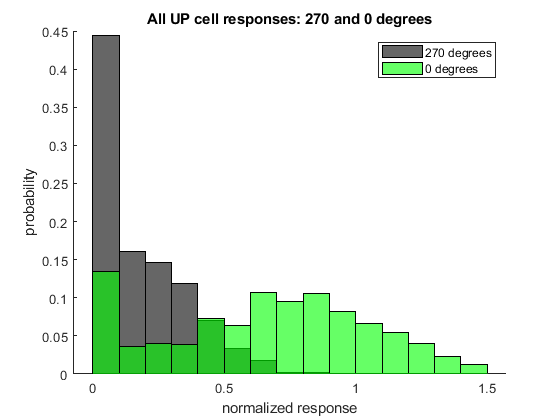

labels =  [zeros(1, numel(allResponses270)), ones(1, numel(allResponses0))];
scores = [allResponses270, allResponses0];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC0 = max([AUC, 1-AUC]);

figure
title('All UP cell responses: 270 and 0 degrees')
hold on
histogram(allResponses270,'BinEdges', edgs, 'FaceColor', 'black', 'Normalization','probability')
histogram(allResponses0, 'BinEdges', edgs,  'FaceColor', 'green', 'FaceAlpha', 0.6, 'Normalization','probability')
xlabel('normalized response')
ylabel('probability')
legend('270 degrees', '0 degrees')

disp(['The ROC AUC for these distributions is ' num2str(AUC0)])

The ROC AUC for these distributions is 0.84211


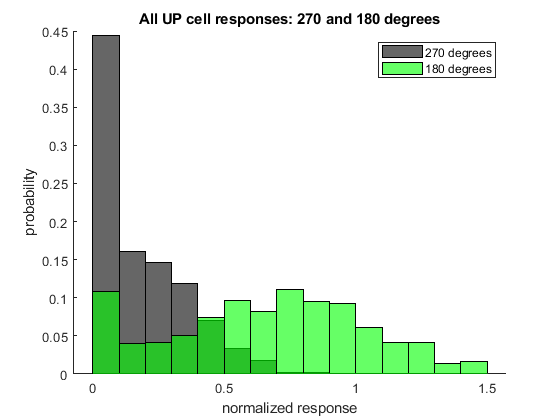


labels =  [zeros(1, numel(allResponses270)), ones(1, numel(allResponses180))];
scores = [allResponses270, allResponses180];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC180 = max([AUC, 1-AUC]);

figure
title('All UP cell responses: 270 and 180 degrees')
hold on
histogram(allResponses270,'BinEdges', edgs, 'FaceColor', 'black', 'Normalization','probability')
histogram(allResponses180, 'BinEdges', edgs,  'FaceColor', 'green', 'FaceAlpha', 0.6, 'Normalization','probability')
xlabel('normalized response')
ylabel('probability')
legend('270 degrees', '180 degrees')

disp(['The ROC AUC for these distributions is ' num2str(AUC180)])

The ROC AUC for these distributions is 0.85786


Interestingly, the system does a bit better at differentiating horizontal motion from downward motion, but it is nonetheless far from optomized.

### Behavioral Predictions

The coordinate system above is based on movement across the retina (e.g. UP cells prefer ventral to dorsal motion on the retina). Therefore, due to the shape of the stimulus space curve I would predict that animals would perform downward OKR better than upward OKR. However, I'm not sure whether OKR gain or another behavioral parameter is the proper measure by which to relate the stimulus space curve to behavior.